clc;
clear all;
l1=30; %Length of Link 1
l2=30; %Length of Link 2
l3=10;  %Length of Link 3
l4 =10; %Length of Link 4

%   DH  = [  a_n  alpha_n  d_n  theta_n]
DHparameter=[0 0 0.04 0;
             0.12 pi/2 0 13*pi/30;
             0.194 0 0 -23*pi/30;
             0 -pi/2 0.176 0;
             0 pi/2 0 pi/2;
             0 pi/2 0 0]

DHparameter =          0         0    0.0400         0
    0.1200    1.5708         0    1.3614
    0.1940         0         0   -2.4086
         0   -1.5708    0.1760         0
         0    1.5708         0    1.5708
         0    1.5708         0         0


%Defining a Robot Rigid Body Tree 
dental = robotics.RigidBodyTree;

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = robotics.RigidBody('Body1');
joint1 = robotics.Joint('Joint1','revolute');
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];
body2 = robotics.RigidBody('Body2');
joint2 = robotics.Joint('Joint2','revolute');
body2.Mass = 10;
body2.CenterOfMass = [0 0 0];
body3 = robotics.RigidBody('Body3');
joint3 = robotics.Joint('Joint3','revolute');
body3.Mass = 10;
joint3.PositionLimits = [-10 10]; %Position limit defines the maximum extension/retraction from mean position for a prismatic joint. 
body3.CenterOfMass = [0 0 0];
body4 = robotics.RigidBody('Body4');
joint4 = robotics.Joint('Joint4','revolute');
body4.Mass = 10;

body5 = robotics.RigidBody('Body5');
joint5 = robotics.Joint('Joint5','revolute');
body5.Mass = 10;

body6 = robotics.RigidBody('Body6');
joint6 = robotics.Joint('Joint6','revolute');
body6.Mass = 10;

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 
setFixedTransform(joint1,DHparameter(1,:),"dh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"dh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"dh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"dh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"dh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"dh");
body6.Joint = joint6;

addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');

showdetails(dental)

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   
--------------------


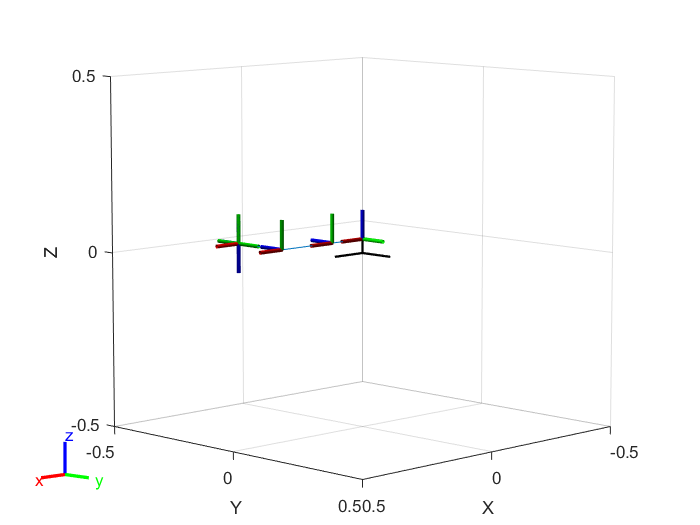


show(dental);